# **Problem 1**

In this problem we will use the implementation of the perceptron algorithm to classify data from two different classes. Before we begin, we will read in the data that we will later use in the following sections.

raw_data = readmatrix('Computer_Assignment_3_Data.xlsx', 'Range', 'B3:I12');
num_samples = size(raw_data, 1);
c1 = raw_data(:,1:2);
c2 = raw_data(:,3:4);
c3 = raw_data(:,5:6);
c4 = raw_data(:,7:8);

## a.

First we will apply the perceptron rule to data from $\omega_1$ and $\omega_2$, we will use label (1) for the first and label (2) for the second class. In order to train the perceptron we will use a the fully documented helper function from "perceptron.mlx". Additionally, we will first take a look at the samples to verify that they are indeed linearly separable.

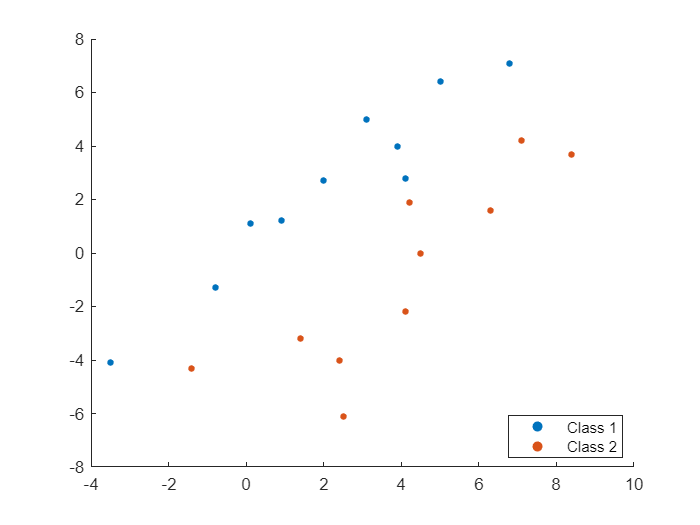

scatter(c1(:, 1), c1(:, 2), 15, 'filled');
hold on
scatter(c2(:, 1), c2(:, 2), 15, 'filled');
legend('Class 1', 'Class 2', 'Location', 'best')
hold off

The classes are indeed lineraly seperable from a visual standpoint.

y_true_a = [ones([num_samples, 1]); 2*ones([num_samples, 1])];
X_a = [c1; c2];
w = perceptron(X_a, y_true_a, 1);

iteration = 20

w =    -3.2000
    1.8000
    1.0000


iteration = 40

w =    -6.4000
    3.6000
    2.0000


iteration = 60

w =    -3.9000
    5.3000
    5.0000


iteration = 80

w =    -7.0000
    6.8000
    6.0000


iteration = 100

w =    -9.4000
    8.4000
    6.0000


iteration = 120

w =   -11.8000
   10.0000
    6.0000


iteration = 140

w =    -9.3000
   11.7000
    9.0000


iteration = 160

w =    -8.7000
   10.4000
   11.0000


iteration = 180

w =    -8.1000
    9.1000
   13.0000


Converged in 180 steps.
Final weights:


w =    -8.1000
    9.1000
   13.0000


We may now draw the decision boundary on top of the previous scatter plot for the final results.

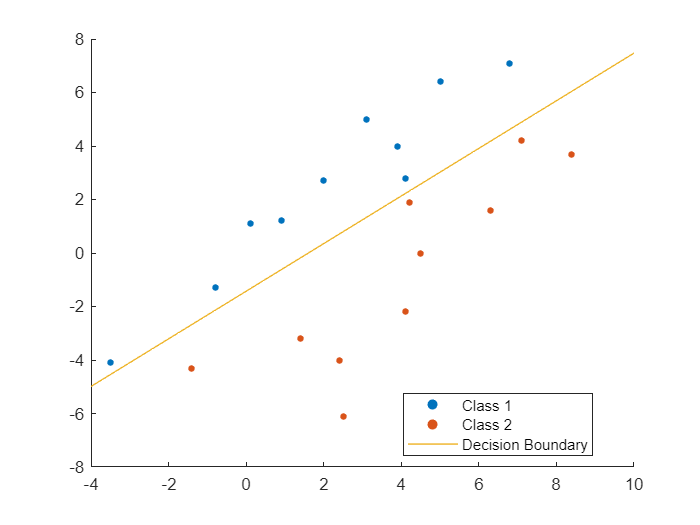

scatter(c1(:, 1), c1(:, 2), 15, 'filled');
hold on
scatter(c2(:, 1), c2(:, 2), 15, 'filled');
hold on
syms x real
decision_boundary = -(w(1)*x + w(3))/w(2);
axis manual
fplot(decision_boundary);
legend('Class 1', 'Class 2', 'Decision Boundary', 'Location', 'best')
hold off

As we can see the algorithm converges in 180 steps and the line can perfectly divide the two classes.

## b.

We will execute the same procedure again for $\omega_2$ (labeled (1)) and $\omega_3$ (labeled (2)).

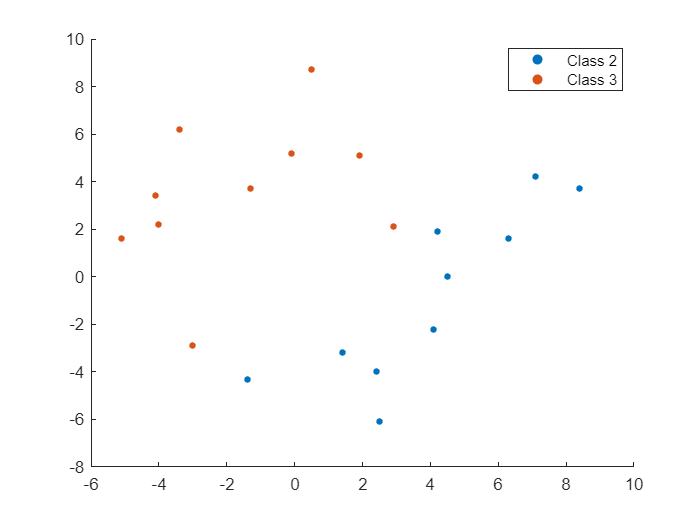

scatter(c2(:, 1), c2(:, 2), 15, 'filled');
hold on
scatter(c3(:, 1), c3(:, 2), 15, 'filled');
legend('Class 2', 'Class 3', 'Location', 'best')
hold off

The classes are indeed lineraly seperable from a visual standpoint.

y_true_b = [ones([num_samples, 1]); 2*ones([num_samples, 1])];
X_b = [c2; c3];
w = perceptron(X_a, y_true_b, 1);

iteration = 20

w =    -3.2000
    1.8000
    1.0000


iteration = 40

w =    -6.4000
    3.6000
    2.0000


iteration = 60

w =    -3.9000
    5.3000
    5.0000


iteration = 80

w =    -7.0000
    6.8000
    6.0000


iteration = 100

w =    -9.4000
    8.4000
    6.0000


iteration = 120

w =   -11.8000
   10.0000
    6.0000


iteration = 140

w =    -9.3000
   11.7000
    9.0000


iteration = 160

w =    -8.7000
   10.4000
   11.0000


iteration = 180

w =    -8.1000
    9.1000
   13.0000


Converged in 180 steps.
Final weights:


w =    -8.1000
    9.1000
   13.0000


We may now draw the decision boundary on top of the previous scatter plot for the final results.

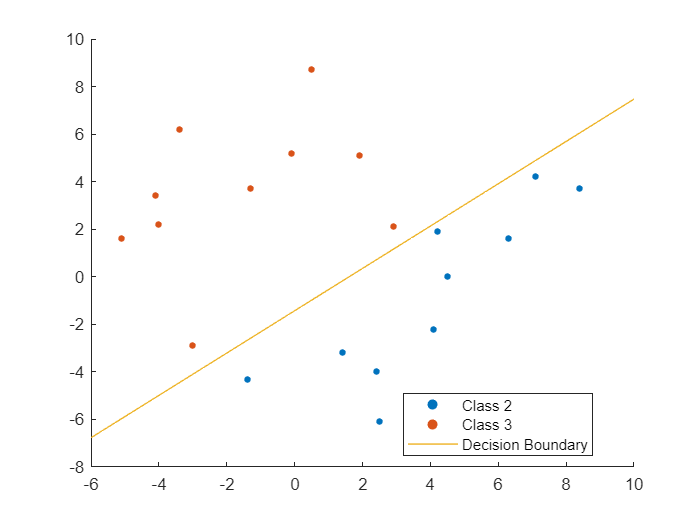

scatter(c2(:, 1), c2(:, 2), 15, 'filled');
hold on
scatter(c3(:, 1), c3(:, 2), 15, 'filled');
hold on
syms x real
decision_boundary = -(w(1)*x + w(3))/w(2);
axis manual
fplot(decision_boundary);
legend('Class 2', 'Class 3', 'Decision Boundary', 'Location', 'best')
hold off

As we can see the algorithm converges in 140 steps and the line can perfectly divide the two classes.

## c.

In order to investigate why the algorithm makes more errors for the first set of data we can take a look at the margin between two data sets. We will define margin as the smallest distance between any two points on of either set.

For $\omega_1$ and $\omega_2$ we have:

margin_1_2 = min(pdist2(c1, c2, "euclidean"), [], 'all')

margin_1_2 = 0.9055

For $\omega_2$ and $\omega_3$ we have:

margin_2_3 = min(pdist2(c2, c3, "euclidean"), [], 'all')

margin_2_3 = 1.3153

As we can see $\textrm{margin}\left(\omega_2 ,\omega_3 \right)>\textrm{margin}\left(\omega_1 ,\omega_2 \right)$which means the algorithm is more likely to stumble upon the correct answer when classifying $\omega_2$ and $\omega_3$ as there are more lines that perfectly separate these two classes than there are for $\omega_1$ and $\omega_2$.

# **Problem 2**

In this problem we are tasked with the implementation of the LS method for the provided dataset.

In order to do this we will use the formulation provided in the slides as:


$$\hat{w} =R_x^{-1} E\left\lbrack x\;y\right\rbrack$$


Where:


$$R_x =E\left\lbrack x\;x^T \right\rbrack$$


We will assume that all the occurance of all of the samples is equiprobable, thereby effectively reducing the expectation in the above formulation to a simple mean value.

## a.

We will apply the LS method to $\omega_1$ and $\omega_2$.

% X_a from the previous section contains all the samples from c1 and c2
% y_true_a also contains all the labels for X_a but we need to encode with
% +1 and -1 for this problem
% We will augment this by a vector of 1s to account for the bias term
y_true_a(y_true_a==1) = -1;
y_true_a(y_true_a==2) = 1;
X_a_aug = [X_a, ones([size(X_a,1), 1])];
% now we can calculate the weights that result in the optimal weights
% w.r.t. the MSE criterion
R_x = (1/size(X_a_aug, 1))*...
    [[X_a_aug(:,1)'*X_a_aug(:,1), X_a_aug(:,1)'*X_a_aug(:,2), X_a_aug(:,1)'*X_a_aug(:,3)];...
     [X_a_aug(:,2)'*X_a_aug(:,1), X_a_aug(:,2)'*X_a_aug(:,2), X_a_aug(:,2)'*X_a_aug(:,3)];...
     [X_a_aug(:,3)'*X_a_aug(:,1), X_a_aug(:,3)'*X_a_aug(:,2), X_a_aug(:,3)'*X_a_aug(:,3)]];
e_x_y = (1/size(X_a_aug, 1))*[X_a_aug(:,1)'*y_true_a; X_a_aug(:,2)'*y_true_a;X_a_aug(:,3)'*y_true_a];
w_hat = inv(R_x)*e_x_y

w_hat =     0.3339
   -0.2879
   -0.7826


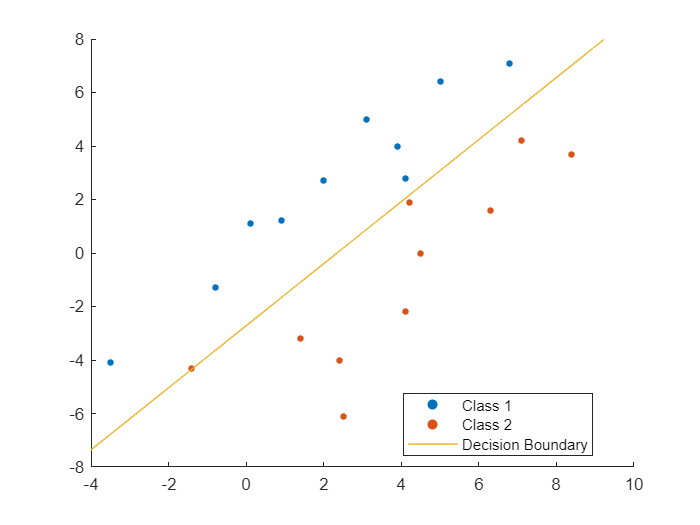

scatter(c1(:, 1), c1(:, 2), 15, 'filled');
hold on
scatter(c2(:, 1), c2(:, 2), 15, 'filled');
hold on
syms x real
decision_boundary = -(w_hat(1)*x + w_hat(3))/w_hat(2);
axis manual
fplot(decision_boundary);
legend('Class 1', 'Class 2', 'Decision Boundary', 'Location', 'best')
hold off

As we can see, this LS-based classifier is prone to making classification errors sometimes but it guarantees that the solution gives has the least squared error possible.

## b.

We will rerun the same experiment for $\omega_3$ (labeled -1) and $\omega_2$ (labeled 1). 

y_true_b(y_true_b==1) = -1;
y_true_b(y_true_b==2) = 1;
X_b_aug = [X_b, ones([size(X_b,1), 1])];
R_x = (1/size(X_b_aug, 1))*...
    [[X_b_aug(:,1)'*X_b_aug(:,1), X_b_aug(:,1)'*X_b_aug(:,2), X_b_aug(:,1)'*X_b_aug(:,3)];...
     [X_b_aug(:,2)'*X_b_aug(:,1), X_b_aug(:,2)'*X_b_aug(:,2), X_b_aug(:,2)'*X_b_aug(:,3)];...
     [X_b_aug(:,3)'*X_b_aug(:,1), X_b_aug(:,3)'*X_b_aug(:,2), X_b_aug(:,3)'*X_b_aug(:,3)]];
e_x_y = (1/size(X_b_aug, 1))*[X_b_aug(:,1)'*y_true_b; X_b_aug(:,2)'*y_true_b;X_b_aug(:,3)'*y_true_b];
w_hat = inv(R_x)*e_x_y

w_hat =    -0.1799
    0.1370
    0.0298


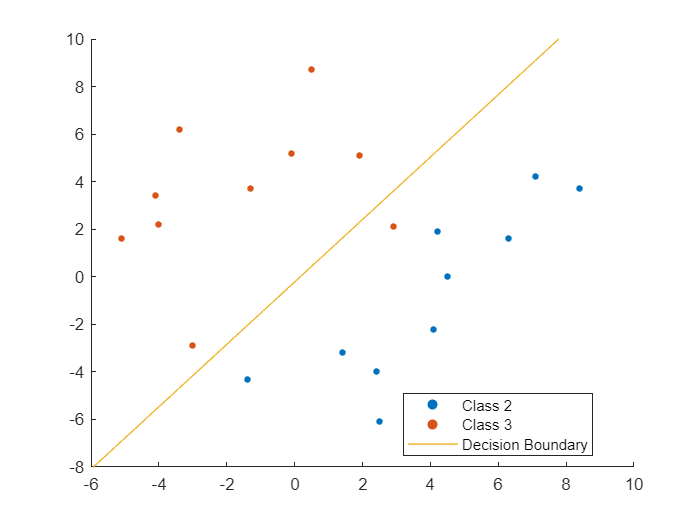

scatter(c2(:, 1), c2(:, 2), 15, 'filled');
hold on
scatter(c3(:, 1), c3(:, 2), 15, 'filled');
hold on
syms x real
decision_boundary = -(w_hat(1)*x + w_hat(3))/w_hat(2);
axis manual
fplot(decision_boundary);
legend('Class 2', 'Class 3', 'Decision Boundary', 'Location', 'best')
hold off

In this case, possibly again due to the wider margin of the two datasets the LS-based method results in a decision boundary with no misclassifications and a guarantee on the least squared error.

# **Problem 3**

In the final section of this assignment, we will perform a multi-class logistic discrimination on all of the available data. According to the problem we will be implementing the multi-class variant of logistic discrimination by performing a series of 2 class discriminations so we will need to only implement the case for 2 classes and then apply the same logic to subsections (a) and (b) of this problem.

According to the slides presented in the class, we will assume that $z=P\left(\omega_1 |x\right)=\sigma \left(w^T x+w_0 \right)$. In order to find $w$ we will need to solve a system of highly nonlinear equations for which we will employ Gradient Descent, an iterative numerical method.

The update rule, again presented in the slides, is as follows:


$$\begin{array}{l}
w_i =w_i +\Delta w_i ,\Delta w_i =-\eta \frac{\partial E\;}{\partial w_i }\;\textrm{where}\;E\;\textrm{is}\;\textrm{the}\;\textrm{crossentropy}\;\textrm{loss}\\
\Delta w_j =-\eta \;\sum_i \left(y_i -z_i \right)x_{\textrm{ij}} ,j=1,2,\cdots ,l\\
\Delta w_0 =-\eta \;\sum_i \left(y_i -z_i \right)\;\\
z_i =\sigma \left(w^T x+w_0 \right)
\end{array}$$


It is also advised that the initial $w$ is drawn from a Standard Normal Distribution ($N\left(0,1\right)$).

This algorithm is implemented in "logistic_discrimination.mlx" and we will use the function documented within this file for the next sections. (answers to section c is included at the end of the descriptions of each of the sections a and b)

## **a.**

Will run the logistic discrimination algorithm in a one-vs-rest manner for all $\omega_i$s.

% concatenate all of the data on to able access them using their indicies
c = cat(3, c1, c2, c3, c4); % c: num_samples x num_features x 4, e.g. c(:,:,4) = c4
w = zeros([3, 1, 4]);
for i=1:4
    fprintf('Calculations for class %d vs. rest...\n', i);
    % singled out class
    curr = c(:,:,i);
    y_curr = ones([size(curr, 1), 1]);
    % rest of the classes
    rest_temp = c(:,:,1:end ~= i);
    % stack them on top of each other
    rest = [rest_temp(:,:,1); rest_temp(:,:,2); rest_temp(:,:,3)];
    y_rest = zeros([size(rest, 1), 1]);
    X = [curr; rest];
    Y = [y_curr; y_rest];
    w(:,:,i) = logistic_discrimination(X,Y);
end

Calculations for class 1 vs. rest...


Stopped in 279 steps.
Final weights:


w =     0.1138
    0.1290
   -1.2712


Calculations for class 2 vs. rest...


Stopped in 2716 steps.
Final weights:


w =     1.1237
   -0.6220
   -3.5520


Calculations for class 3 vs. rest...


Stopped in 788 steps.
Final weights:


w =    -0.3963
    0.5943
   -2.1473


Calculations for class 4 vs. rest...


Stopped in 5000 steps.
Final weights:


w =    -1.6833
   -1.4958
  -12.7035


We can now plot the data and their discriminators to see how they've done.

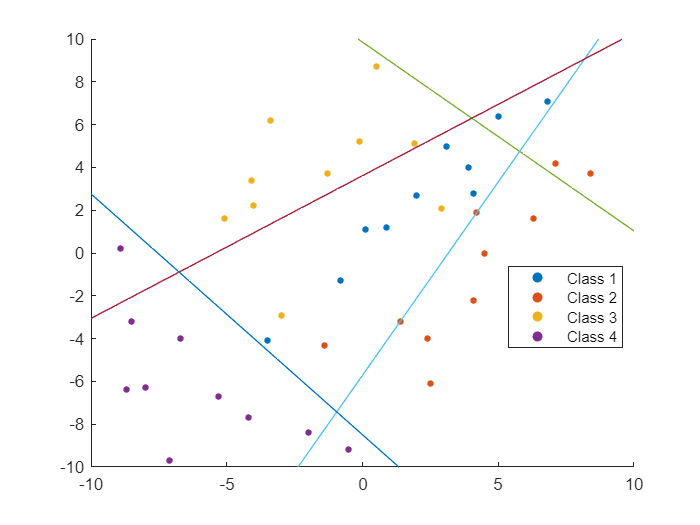

scatter(c1(:, 1), c1(:, 2), 15, 'filled');
hold on
scatter(c2(:, 1), c2(:, 2), 15, 'filled');
scatter(c3(:, 1), c3(:, 2), 15, 'filled');
scatter(c4(:, 1), c4(:, 2), 15, 'filled');
syms x1 x2 real
X = [x1; x2; 1];
% to avoid having to plot in a 3D space, decision boundary was assumed
% to be the point at which the sigmoid gives
% exactly 0.5
db = cell(4, 1);
for i=1:4
    db{i} = solve(logsig(w(:,:,i)'*X) == 0.5, x2);
end
axis manual
for i=1:4
    fplot(db{i})
end
legend('Class 1', 'Class 2', 'Class 3', 'Class 4', 'Location', 'best')
hold off

As we can see, aside from the discriminator for the first class (green line in the figure above) the rest of the discriminators are working fairly well. The reason the first discriminator is failing is because the first class (blue points) is simply not linearly separable from the rest of the dataset while other classes do indeed have this property. This issue can be alleviated using a pairwise discrimination scheme since while this class is not linearly seperable from the rest of the dataset, it is still linearly seperable from each class individually.

**c.**

Because we haven't used a minimal distance (maximum probability) scheme, it is clear that these classifiers partition the space into area where the decision is ambiguous. These areas can be obtained from solving the equations ${\textrm{db}}_i ={\textrm{db}}_j$ for each of obtained decision boundaries. These will give the points of intersection of two decision boundaries. The areas that lie on the positive side of both of ${\textrm{db}}_i \;$and ${\textrm{db}}_j$ for some $i$ and $j$, is ambiguous. Additionally, the area that lies on the negative side of all of the decision boundaries is also ambiguous as it is implied that it belongs to none of the classes.

An example of this is given in the image below:

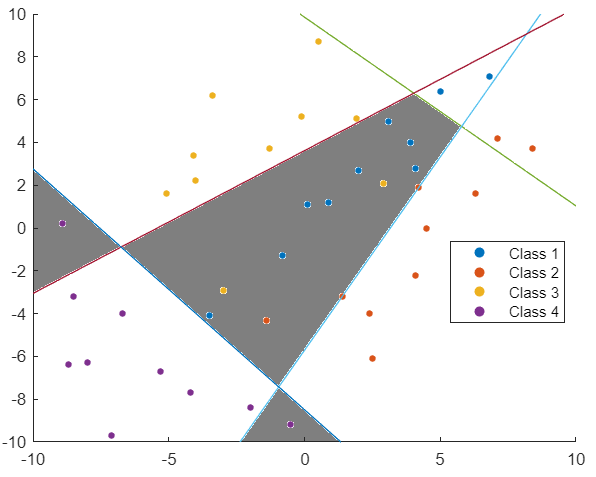

The decision in the gray shaded areas in the figure above is ambiguous.

## b.

We will repeat the same procedure except this time we will use a pairwise discrimination.

% the vector in w(:,:,i,j) is the learned weights of the discriminator of
% class i against class j.
% note that w(:,:,j,i) is assumed the same as w(:,:,i,j) because the same
% discriminator can separate both cases with a change in the direction of
% its weight vector.
w = zeros([3, 1, 4, 4]);
for i=1:3
    for j=i+1:4
    fprintf('Calculations for class %d vs. class %d...\n', i, j);
    % current class
    curr = c(:,:,i);
    y_curr = ones([size(curr, 1), 1]);
    % other class
    other = c(:,:,j);
    % stack them on top of each other
    y_other = zeros([size(other, 1), 1]);
    X = [curr; other];
    Y = [y_curr; y_other];
    w(:,:,i,j) = logistic_discrimination(X,Y);
    w(:,:,j,i) = w(:,:,i,j);
    end
end

Calculations for class 1 vs. class 2...


Stopped in 5000 steps.
Final weights:


w =    -4.4801
    4.6749
    7.4399


Calculations for class 1 vs. class 3...


Stopped in 1174 steps.
Final weights:


w =     1.1037
   -0.7805
    1.2524


Calculations for class 1 vs. class 4...


Stopped in 5000 steps.
Final weights:


w =     1.3136
    1.1707
    9.5857


Calculations for class 2 vs. class 3...


Stopped in 5000 steps.
Final weights:


w =     3.9684
   -4.2316
   -5.3002


Calculations for class 2 vs. class 4...


Stopped in 5000 steps.
Final weights:


w =     1.5088
    1.1855
    8.8966


Calculations for class 3 vs. class 4...


Stopped in 5000 steps.
Final weights:


w =     1.4390
    1.3272
    9.7112


We can now plot the data and their discriminators to see how they've done.

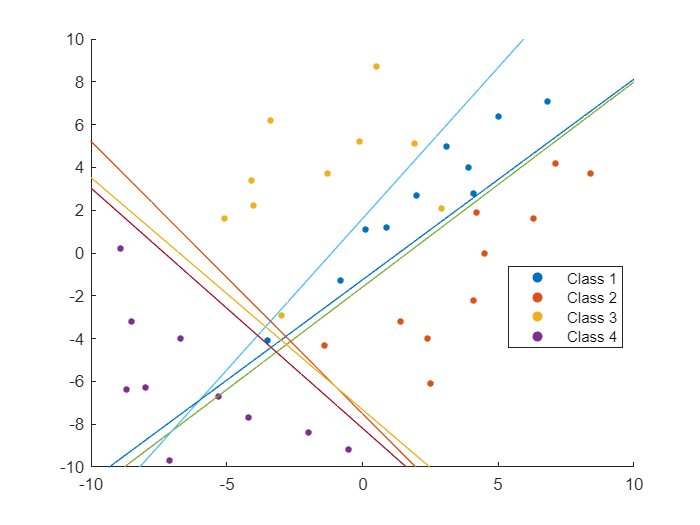

scatter(c1(:, 1), c1(:, 2), 15, 'filled');
hold on
scatter(c2(:, 1), c2(:, 2), 15, 'filled');
scatter(c3(:, 1), c3(:, 2), 15, 'filled');
scatter(c4(:, 1), c4(:, 2), 15, 'filled');
syms x1 x2 real
X = [x1; x2; 1];
% to avoid having to plot in a 3D space, decision boundary was assumed
% to be the point at which the sigmoid gives
% exactly 0.5
db = cell(6, 1);
count = 1;
for i=1:3
    for j=i+1:4
        db{count} = solve(logsig(w(:,:,i,j)'*X) == 0.5, x2);
        count = count + 1;
    end
end
axis manual
for i=1:count-1
    fplot(db{i})
end
legend('Class 1', 'Class 2', 'Class 3', 'Class 4', 'Location', 'best')
hold off

**c.**

Here we also have the same ambiguity issue as the previous part, however, if we were to choose a max probability scheme, we would be able to perfectly classify all of the classes with no ambiguity at all. This was not possible in the previous section because the one vs. rest classifier wouldn't work for $\omega_1$. 

This scheme would eventually look something like this:

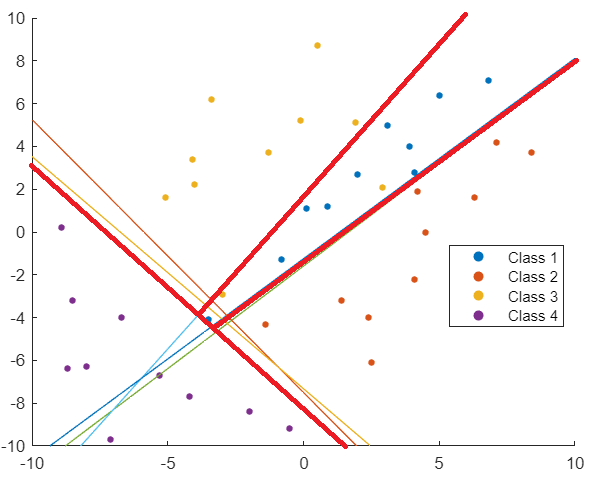

Where the thick red lines are the final discriminants. These discriminants cause no ambiguity and can perfectly classify the entire dataset.